clc; clear; close all; addpath z_toolbox\Violinplot;
addpath E:\IEDpropagation\z_toolbox\IEEGworkbench\function;
subG = {'sub-0001', 'sub-0002', 'sub-0003', 'sub-0004', 'sub-0005', ...
        'sub-0007', 'sub-0008', 'sub-0009', 'sub-0010', 'sub-0011', ...
        'sub-0012', 'sub-0013', 'sub-0014', 'sub-0015', 'sub-0016', ...
        'sub-0017', 'sub-0019', 'sub-0020', 'sub-0021', 'sub-0022', ...
        'sub-0023', 'sub-0028', 'sub-0029', 'sub-0031', 'sub-0033', ...
        'sub-0034', 'sub-0035', 'sub-0036', 'sub-0039', 'sub-0046', ...
        'sub-0047', 'sub-0050', 'sub-0052', 'sub-0054', 'sub-0062', ...
        'sub-0063', 'sub-0066', 'sub-0067', 'sub-0074', 'sub-0077', ...
        'sub-0087', 'sub-0089', 'sub-0092', 'sub-0093', 'sub-0094', ...
        'sub-0113', 'sub-0115'};
ASEGlabels = {'Acc', 'Amy', 'Cau', 'Hip', 'Pal', 'Put', 'Tha', 'VDC'};
Yeo7labels = {'Vis', 'SM', 'DA.FEF', 'DA.Post', ...
                'SA.FOI', 'SA.Med', 'SA.PFCl', 'SA.PFCv', 'SA.PO', ...
                'SA.PrC', 'SA.TOP', ...
                'C.Cing', 'C.OFC', 'C.PFCl', 'C.PFCmp', 'C.PFCv', ...
                'C.Par', 'C.Temp', 'C.pCun', ...
                'Lim.OFC', 'Lim.TP', ...
                'D.PFC', 'D.PFCdm', 'D.PFCv', 'D.PHC', 'D.Par', ...
                'D.Temp', 'D.pCun'};
JHUlabels = {'SupFroB', 'MidFroB', 'InfFroB', 'FroOccF', ...
            'SupLonF', 'PreCenB' 'PoCenB', 'SupParB', ...
            'ParTempB', 'TempB', 'OccB', 'CorRadT', 'ThaRadT', ...
            'IntCapT', 'ExtCapT', 'SagStrT', 'CingT', ...
            'CorCalT', 'UncF'};
elecPath = 'step1_AwakeSEEG_BPfiltering_Age16Up';
seegPath = 'step2_SEEG_TCAR_BPF';
cortexContactN = 0; whiteContactN = 0; subcortexContactN = 0;
Yeo7number = zeros(length(Yeo7labels), 1);
ASEGnumber = zeros(length(ASEGlabels), 1);
JHUnumber = zeros(length(JHUlabels), 1);
for nS = 1:length(subG)
    subID = subG{nS};
    load(fullfile(elecPath, subID, [subID, '_ROI-3mm_contactAnatomy.mat']));
    rawContactNumber(nS) = length(contAnat.label);
    chanGroup = f_chanGroup(contAnat.label);
    contactNumber = tabulate(chanGroup);
    contactNumber = contactNumber(:, 2);
    contactNumber = cell2mat(contactNumber);
    minCN(nS) = min(contactNumber);
    maxCN(nS) = max(contactNumber);
    seegFilerDir = dir(fullfile(seegPath, subID, [subID, '_task-rest_run-*_TCAR_BPF.mat']));
    dataLength(nS) = 5*length(seegFilerDir);
    load(fullfile(seegFilerDir(1).folder,  seegFilerDir(1).name));
    for nC = 1:length(data.label)
        a = strcmp(data.label{nC}, contAnat.label);
        if any(a)
            if strcmp(contAnat.CWS{a==1}, 'Cortex')
                cortexContactN = cortexContactN + 1;
            end
            if strcmp(contAnat.CWS{a==1}, 'White')
                whiteContactN = whiteContactN + 1;
            end
            if strcmp(contAnat.CWS{a==1}, 'Subcortex')
                subcortexContactN = subcortexContactN + 1;
            end
            b = strcmp(contAnat.Yeo7_51{a==1}, Yeo7labels);
            Yeo7number(b==1) = Yeo7number(b==1)+1;
            b = strcmp(contAnat.ASEG{a==1}, ASEGlabels);
            ASEGnumber(b==1) = ASEGnumber(b==1)+1;
            b = strcmp(contAnat.JHU{a==1}, JHUlabels);
            JHUnumber(b==1) = JHUnumber(b==1)+1;
        end
    end
end
disp(sum(rawContactNumber));

        4252



disp(cortexContactN+whiteContactN+subcortexContactN);

        4010



disp(cortexContactN);

        1706



disp(whiteContactN);

        1856



disp(subcortexContactN);

   448



disp(mean(dataLength));

   87.3404



disp(std(dataLength));

   67.3073



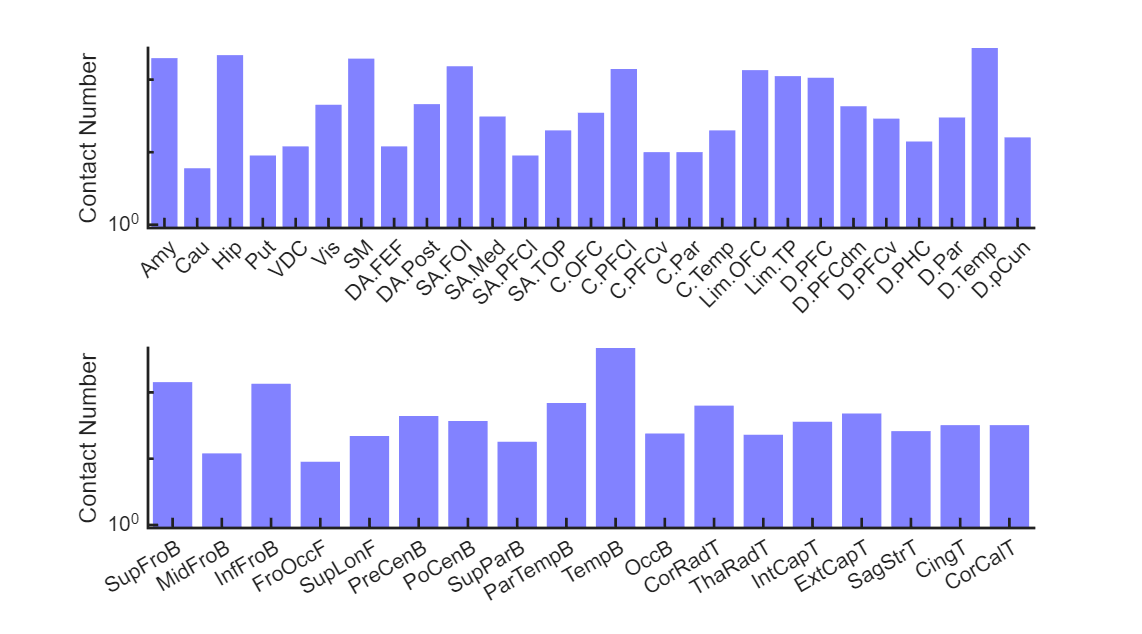

% figure of contact number in cortex and subcortex
Yeo7labels = [ASEGlabels, Yeo7labels];
Yeo7number = [ASEGnumber; Yeo7number];
idx = find(Yeo7number>=5);
Yeo7labels = Yeo7labels(idx);
Yeo7number = Yeo7number(idx);
figure('Units', 'centimeters', 'Position', [5, 5, 36, 20]);
subplot(2, 1, 1);
bar(Yeo7number, 'FaceColor', [0.51 0.51 1], 'EdgeAlpha', 0);
ylabel('Contact Number');
set(gca, 'YScale', 'log');
ylim([0.9, max(Yeo7number)]);
xlim([0.5, length(Yeo7number)+0.5]);
xticks(1:length(Yeo7number));
xticklabels(Yeo7labels);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
% figure of contact number in cortex and subcortex
idx = find(JHUnumber>=5);
JHUlabels = JHUlabels(idx);
JHUnumber = JHUnumber(idx);
subplot(2, 1, 2);
bar(JHUnumber, 'FaceColor', [0.51 0.51 1], 'EdgeAlpha', 0);
ylabel('Contact Number');
set(gca, 'YScale', 'log');
ylim([0.9, max(JHUnumber)]);
xlim([0.5, length(JHUnumber)+0.5]);
xticks(1:length(JHUnumber));
xticklabels(JHUlabels);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);